# SSCmetrics

## Objective

The goal of this MATLAB live file is to show and explain all the processing steps and Matlab commands required to compute the five metrics of the Soundscape Code (Wilford et al. 2021). The example below uses data from a SoundTrap ST600 (Ocean Instruments, New Zealand) deployed in Lizard Island, Great Barrier Reef, Australia. The example audio file (.wav) is a five minute recording, using high gain, and 48 kHz sampling rate. The audio file is calibrated and processed into four one-minute segments, following the one-minute length files in Wilford et al. (2021). Thus, this code computes and stores the Soundscape Code metrics for each one-minute segment. Consider that this code is meant to show how the code works on a single example and for our instrument. For batch processing and other instruments, the code should be modified to consider noise removal, instrument-specific calibration, and loops for batch processing. Below we provide the code with a brief exaplanation, following the equations in Wilford et al. (2021) and updates of terminology in ISO (2017).

**References:**

- Wilford DC, Miksis-Olds JL, Martin SB, Howard DR, Lowell K, Lyons AP, Smith MJ. 2021. Quantitative soundscape analysis to understand multidimensional features. Frontiers in Marine Science *8*, 672336. 10.3389/fmars.2021.672336.

- ISO. 2017. 18405.2. Underwater Acoustics—Terminology. International Organization for Standardization, Geneva.

## Soundscape Code (SSC)

This soundscape analysis approach was developed to aid in the optimal and accurated soundscape comparisons. The SSC consists of five metrics the summarize four key soundscape atrtibutes with acoustic and ecological relevance:

- Amplitude: Root-mean-square sound pressure level ($L_{p,rms}$); Maximum sound pressure level ($L_{p,pk}$).

- Impulsiveness: Kurtosis of the sound pressure level ($\beta$).

- Periodicity: Time-lagged autocorrelation for 0.1 s mean square sound pressure averages ($Acorr3$).

- Uniformity: Dissimilarity index ($D$).

## Structure of the code

The code is structured in # steps:

- Step 1: Defining directories, calibration values, empty matrices.

- Step 2: Pre-processing, calibration, Short-Time Fourier Transform, and datetime data.

- Step 3: Extracting bands of interest.

- Step 4: Reshaping waveform of extracted bands of interest

- Step 5: Amplitude: Root-mean-square sound pressure level ($L_{p,rms}$).

- Step 6: Amplitude: Maximum sound pressure level ($L_{p,pk}$).

- Step 7: Impulsiveness: Kurtosis of the sound pressure level ($\beta$).

- Step 8: Periodicity: Time-lagged autocorrelation for 0.1 s mean square sound pressure averages ($Acorr3$).

- Step 9: Uniformity: Dissimilarity index ($D$).

- Step 10: Store and export outcomes

## Step 1: Defining directories, calibration values, empty matrices

Define the directory of the WAV files that are going to be processed and the directory where we are going to store the SSC results. If you are running this code on MATLAB Online, you should have code lines that setup of directories from the GitHub and MATLAB Online repository ready to run the code. If you are running this code on MATLAB desktop, you should modify the code accordingly to define your local directories.

% Get the root folder of the current project
project = currentProject;
projectRoot = project.RootFolder; 

% Define the working directory
cd(projectRoot);

% Define the directories
wav_directory = fullfile(projectRoot, 'data', '7255');
results_directory = fullfile(projectRoot, 'results');

% Check if directories exist
if ~isfolder(wav_directory)
    error('WAV directory does not exist: %s', wav_directory);
end

if ~isfolder(results_directory)
    error('Results directory does not exist: %s', results_directory);
end

The example WAV file provided here was recorded using the SoundTrap ST600 serial number 7255:

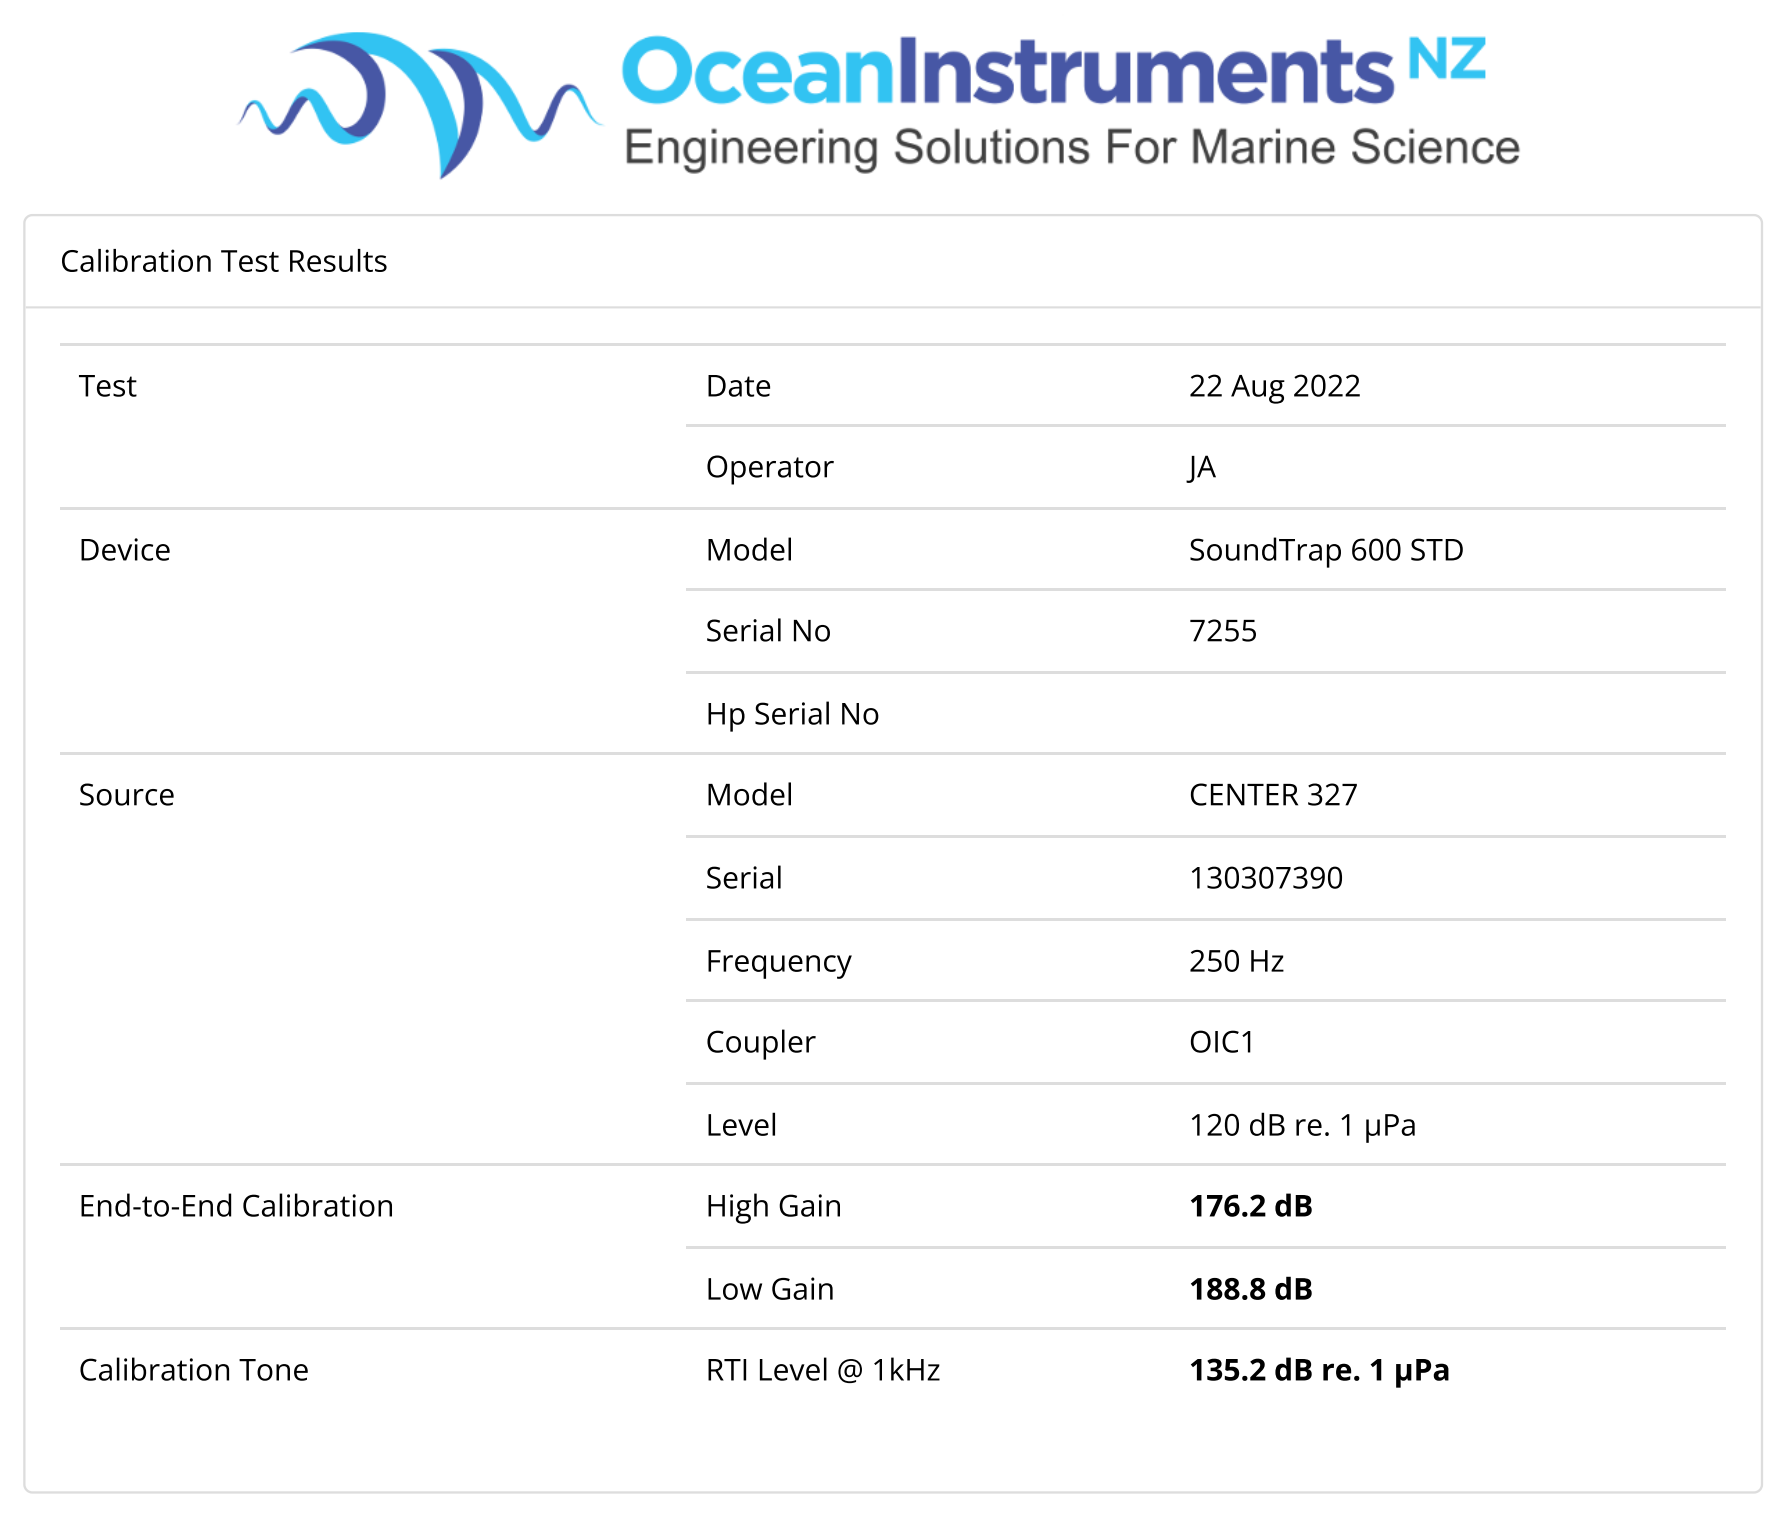

[Source: OceanInstrumentsNZ [https://oceaninstruments.azurewebsites.net/App/#/%23](https://oceaninstruments.azurewebsites.net/App/#/%23)]

Consult manufacturer about the calibration of your instrument. In the case of this example, the recording was conducted using high gain, therefore the value to use is 176.2 dB.

Set the calibration value (dB re 1 microPa) of the recording instrument. This value should be checked for each instrument according to manufacturer,

cal = -176.2; 

Set channels to use.

ch2use = 1;

List and display the contents of the folder. In this case, the contents in .wav format.

wav_files = dir(fullfile(wav_directory, '*.wav'));
disp(['Number of WAV files found: ', num2str(length(wav_files))]);

Number of WAV files found: 1


Create empty matrices to store results

%General
Files_name = [];
Files_datetime = [];
Files_date = [];
Files_time = [];
%Broadband
Files_Lprms_broad = [];
Files_Lppk_broad = [];
Files_B_broad = [];
Files_Acorr3_broad = [];
Files_D_broad = [];
%Fish
Files_Lprms_fish = [];
Files_Lppk_fish = [];
Files_B_fish = [];
Files_Acorr3_fish = [];
Files_D_fish = [];
%Invertebrate
Files_Lprms_invertebrate = [];
Files_Lppk_invertebrate = [];
Files_B_invertebrate = [];
Files_Acorr3_invertebrate = [];
Files_D_invertebrate = [];

## Step 2: Pre-processing, calibration, Short-Time Fourier Transform, datetime data

Extract file information, calibrate the waveform according to manufacturer, cut out the first three seconds of recording (our instrument produced noise at the beginning of each recording), and compute the Short-Time Fourier Transform (STFT) of the waveform to obtain a spectrogram.

[pathstr,fname,ext] = fileparts(wav_files(1).name); % extract path name, file name, and extension
[wf, fs] = audioread(fullfile(wav_directory, wav_files(1).name)); % extract data (waveform) and sample rate
p = wf(:,ch2use); % p is data; if multiple channels, data is now one channel
p2 = p * (10.^(abs(cal)/20)); % p2 is calibrated pressure
p2 = p2(3 * fs : end); % cut first three seconds
NFFT = fs; % window length = 1 s if NFFT = fs
[S,F,T,P] = spectrogram(p2,NFFT,NFFT/2,NFFT,fs,'yaxis'); % compute Short-Time Fourier Transform (STFT) of the waveform
P(1,:) = []; % removes first row of FFT matrix (0 Hz)
F(1,:) = []; % removes first row of FFT matrix (0 Hz)

Extract and store datetime data. This section should be adapted accordingly to fit the structure of your metadata.

% Convert file name to string and format datetime
fname = convertCharsToStrings(fname);
fdatetime = extractAfter(fname, ".");
fdatetime = insertAfter(fdatetime, 10, ":");
fdatetime = insertAfter(fdatetime, 8, ":");
fdatetime = insertAfter(fdatetime, 6, " ");
fdatetime = insertAfter(fdatetime, 4, "-");
fdatetime = insertAfter(fdatetime, 2, "-");
fdatetime = insertAfter(fdatetime, 0, "20");

% Convert to datetime object
datetime_obj = datetime(fdatetime, 'InputFormat', 'yyyy-MM-dd HH:mm:ss');
date_str = datestr(datetime_obj, 'yyyy-mm-dd');
time_str = datestr(datetime_obj, 'HH:MM:SS');

% Repeat each entry 4 times and append to the arrays
Files_name = repmat({fname}, 4, 1); % Only keep this repmat
Files_datetime = repmat({datetime_obj}, 4, 1);
Files_date = repmat({date_str}, 4, 1);
Files_time = repmat({time_str}, 4, 1);

## Step 3: Extracting bands of interest

Define the bands of interest for the analysis. In our soundscape, the biological components that have more conspicuous contributions are fish and invertebrates, in the frequency ranges of 200 Hz - 800 Hz and 2 khz - 5 kHz, respectively. In addition, we also consider the broad band, but excluding frequencies below 200 Hz to avoid instrument self-noise.

Extract the bands of interest from the waveform (p2):

%Broadband
broad = highpass(p2,200,fs); % returns highpass filtered signal above 200 Hz
%Fish band
fish = bandpass(p2,[200 800],fs); % returns bandpass filtered signal between 200 Hz and 800 Hz focusing on coral reef fish sounds
%Invertebrate band
invertebrate = bandpass(p2,[2000 5000],fs); % returns bandpass filtered signal between 2 kHz and 5 kHz focusing on snapping shrimp sounds   

## Step 4: Reshaping waveform of extracted bands of interest

The original Soundscape Code (SSC) description (Wilford et al. 2021) uses one-minute recordings to compute the five SSC metrics. In our sampling, we recorded five-minute recordings every 15 minutes. In addition, we cut the first three seconds of every recording due to a click noise at the beginning of each recoring. Consequently, our waveforms and spectrograms are 297 s length. For most metrics, we only selected the first four one-minute segments (240 s), since the last segment is 57 s. See below a different approach for the dissimilarity index ($D$).

Reshape waveform into four separate one-minute observation windows. Consider that the waveform (input signal) is a vector with 48 kHz sampling rate (fs). The code reshapes the vector into a matrix, with fs*60 rows and 4 columns.

%Broadband
broad_Tobs = reshape(broad(1:240*fs),[fs*60,4]);
%Fish band
fish_Tobs = reshape(fish(1:240*fs),[fs*60,4]);
%Invertebrate band
invertebrate_Tobs = reshape(invertebrate(1:240*fs),[fs*60,4]);

## Step 5: Amplitude: Root-mean-square sound pressure level ($L_{p,rms}$)

Is the level of the field quantity root-mean-square sound pressure:


$$L_{p,rms} =20\log_{10} \left(\sqrt{\frac{\bar{p^2 } }{p_0 }}\right)$$


where $p_0$ is the reference value of sound pressure (1 µPa), $p$ is the instantaneous pressure.

%Broadband
Lprms_broad_Tobs = 20*log10(sqrt(sum(broad_Tobs.^2,1)/(fs*60)));
Files_Lprms_broad = [Files_Lprms_broad,Lprms_broad_Tobs];
%Fish band
Lprms_fish_Tobs = 20*log10(sqrt(sum(fish_Tobs.^2,1)/(fs*60)));
Files_Lprms_fish = [Files_Lprms_fish,Lprms_fish_Tobs];
%Invertebrate band
Lprms_invertebrate_Tobs = 20*log10(sqrt(sum(invertebrate_Tobs.^2,1)/(fs*60)));
Files_Lprms_invertebrate = [Files_Lprms_invertebrate,Lprms_invertebrate_Tobs];

## Step 6: Amplitude: Maximum sound pressure level ($L_{p,pk}$)

Is the level of the field quantity sero-to-peak sound pressure:


$$L_{p,pk} =10\log_{10} \left(\frac{p_{\textrm{pk}} }{p_0 }\right)$$


where $p_0$ is the reference value of sound pressure (1 µPa), $p_{\textrm{pk}}$ is the zero-to-peak sound pressure (i.e. the greatest magnitude of the instantaneous sound pressure).

%Broadband
Lppk_broad_Tobs = 10*log10(max((broad_Tobs.^2),[],1));
Files_Lppk_broad = [Files_Lppk_broad,Lppk_broad_Tobs];
%Fish band
Lppk_fish_Tobs = 10*log10(max((fish_Tobs.^2),[],1));
Files_Lppk_fish = [Files_Lppk_fish,Lppk_fish_Tobs];
%Invertebrate band
Lppk_invertebrate_Tobs = 10*log10(max((invertebrate_Tobs.^2),[],1));
Files_Lppk_invertebrate = [Files_Lppk_invertebrate,Lppk_invertebrate_Tobs];

## Step 7: Impulsiveness: Kurtosis of the sound pressure level ($\beta$)

Kurtosis is a statistical measure that describes the shape of a distribution. More specifically, how "heavy" or "light" the tails of the distribution are compred to a normal distribution. In the case of the sound pressure, kurtosis is considered as an indicator of the impulsiveness. It is usually driven by the presence of sounds with a short duration, rapid- or pulse-rise time, and high sound levl. Many underwater sounds have a pulsed acoustic signature, making the kurtosis a proxy for the presence of thesekinds of sounds.

Kurtosis of the sound pressure is speecified over  a time interval $t_1$ to $t_2$:


$$\beta =\frac{\mu_4 }{\mu_2 }$$


where $\mu_4$ is:


$$\mu_4 =\frac{1}{t_2 -t_1 }\int_{t_1 }^{t_2 } {\left\lbrack p\left(t\right)-\bar{p} \right\rbrack }^4 \textrm{dt}$$


$\mu_2$ is the sound pressure variance:


$$\mu_2 =\frac{1}{t_2 -t_1 }\int_{t_1 }^{t_2 } {\left\lbrack p\left(t\right)-\bar{p} \right\rbrack }^2 \textrm{dt}$$


$\bar{p}$ is the mean sound pressure.

MATLAB computes kurtosis following these equations with the in-builf functions *kurtosis*.

%Broadband
B_broad_Tobs = kurtosis(reshape(broad_Tobs, fs*60, 4), 0, 1);
Files_B_broad = [Files_B_broad,B_broad_Tobs];
%Fish band
B_fish_Tobs = kurtosis(reshape(fish_Tobs, fs*60, 4), 0, 1);
Files_B_fish = [Files_B_fish,B_fish_Tobs];
%Invertebrate band
B_invertebrate_Tobs = kurtosis(reshape(invertebrate_Tobs, fs*60, 4), 0, 1);
Files_B_invertebrate = [Files_B_invertebrate,B_invertebrate_Tobs];

## Step 8: Periodicity: Time-lagged autocorrelation for 0.1 s mean square sound pressure averages ($Acorr3$)

This is a measure that counts peaks above a prominence threshold. In this study, this metric uses averaged pressure time series each 0.1 s, counting the peaks in  autocorrelation using a threshold for a minimum peak prominence of $p_{\gamma \gamma } \left(t,t+\tau \right)=0\ldotp 5$. This measurement mainly targets stridulatory sounds of biological origin (trains of pulses), which might be interpreted as sounds that are periodic within one-minute.

%Broadband
broad_Tobs_cs = squeeze(mean(reshape(broad_Tobs, (0.1 * fs), [], size(broad_Tobs, 2)), 1)); % Compute mean sound pressure across 0.1 seconds
xcorr_broad_Tobs_cs = zeros([],[]);
for i = 1:size(broad_Tobs_cs,2)
    xcorr_broad_Tobs_cs(:,i) = xcorr(broad_Tobs_cs(:,i),'normalized');
end
Acorr3_broad_Tobs_cs = zeros([],[]); %create empty matrix to fill with number of peaks of autocorrelation
for i = 1:size(xcorr_broad_Tobs_cs,2) %run the next code for each column
    Acorr3_broad_Tobs_cs(:,i) = numel(findpeaks(xcorr_broad_Tobs_cs(:,i),'MinPeakProminence',0.1)); %counts peaks of autocorrelation
end
Files_Acorr3_broad = [Files_Acorr3_broad, Acorr3_broad_Tobs_cs];
%Fish band
fish_Tobs_cs = squeeze(mean(reshape(fish_Tobs, (0.1 * fs), [], size(fish_Tobs, 2)), 1)); % Compute mean sound pressure across 0.1 seconds
xcorr_fish_Tobs_cs = zeros([],[]);
for i = 1:size(fish_Tobs_cs,2)
    xcorr_fish_Tobs_cs(:,i) = xcorr(fish_Tobs_cs(:,i),'normalized');
end
Acorr3_fish_Tobs_cs = zeros([],[]); %create empty matrix to fill with number of peaks of autocorrelation
for i = 1:size(xcorr_fish_Tobs_cs,2) %run the next code for each column
    Acorr3_fish_Tobs_cs(:,i) = numel(findpeaks(xcorr_fish_Tobs_cs(:,i),'MinPeakProminence',0.1)); %counts peaks of autocorrelation
end
Files_Acorr3_fish = [Files_Acorr3_fish, Acorr3_fish_Tobs_cs];
%Invertebrate band
invertebrate_Tobs_cs = squeeze(mean(reshape(invertebrate_Tobs, (0.1 * fs), [], size(invertebrate_Tobs, 2)), 1)); % Compute mean sound pressure across 0.1 seconds
xcorr_invertebrate_Tobs_cs = zeros([],[]);
for i = 1:size(invertebrate_Tobs_cs,2)
    xcorr_invertebrate_Tobs_cs(:,i) = xcorr(invertebrate_Tobs_cs(:,i),'normalized');
end
Acorr3_invertebrate_Tobs_cs = zeros([],[]); %create empty matrix to fill with number of peaks of autocorrelation
for i = 1:size(xcorr_invertebrate_Tobs_cs,2) %run the next code for each column
    Acorr3_invertebrate_Tobs_cs(:,i) = numel(findpeaks(xcorr_invertebrate_Tobs_cs(:,i),'MinPeakProminence',0.1)); %counts peaks of autocorrelation
end
Files_Acorr3_invertebrate = [Files_Acorr3_invertebrate, Acorr3_invertebrate_Tobs_cs];

## Step 10: Uniformity: Dissimilarity index ($D$)

This is $\beta$-index that measures between-group differences in the signal changes over time, in terms of temporal and spectral attributes. In this case between the consecutive 1-minute observation windows from each recording.

**Reshape waveform for dissimilarity index (**$D$**)**

The dissimilarity index is a $\beta$-index that measures between-group differences in terms of temporal and frequency attributes. Since our recordings are 297 s length, we can reshape them into four one-minute segments and one 57 s segment. In order to obtain four values of the dissimilarity index ($D$) we extracted the first four one-minute segments, and one additional one-minute segment counting backwards 60 seconds from the end of the recordings. Thus, the fourth and fifth one-minute segments overlap in 3 seconds. After this reshaping, we will have four measures of the between group differences between: first and second segments, second and third segments, third and fourth segments, and fourth and fifth segments.

%Broadband
broad_Tobs_first4min = reshape(broad(1:240*fs),[fs*60,4]);
broad_Tobs_last1min = reshape(broad(length(broad)-((60*fs)-1):length(broad)),[fs*60,1]);
broad_Tobs_5min = cat(2,broad_Tobs_first4min,broad_Tobs_last1min);
%Fish band
fish_Tobs_first4min = reshape(fish(1:240*fs),[fs*60,4]); %reshapes the filtered input signal, vector to matrix, where columns are one minute of recording (observation window)
fish_Tobs_last1min = reshape(fish(length(fish)-((60*fs)-1):length(fish)),[fs*60,1]);
fish_Tobs_5min = cat(2,fish_Tobs_first4min,fish_Tobs_last1min);
%Invertebrate band
invertebrate_Tobs_first4min = reshape(invertebrate(1:240*fs),[fs*60,4]); %reshapes the filtered input signal, vector to matrix, where columns are one minute of recording (observation window)
invertebrate_Tobs_last1min = reshape(invertebrate(length(invertebrate)-((60*fs)-1):length(invertebrate)),[fs*60,1]);
invertebrate_Tobs_5min = cat(2,invertebrate_Tobs_first4min,invertebrate_Tobs_last1min);

The $D$ is computed using the probability mass function of the amplitude envelope calculated from te analytic signal ($\zeta \left(t\right)$) to calculate the temporal dissimilarity ($D_t$); and the mean spectrum ($\bar{s\left(f\right)}$) to calculate the spectral dissimilarity ($D_f$).

**Dissimilarity index (**$D$**):**


$$D=D_t \times {\;D}_f$$


**Temporal dissimilarity (**$D_t$**):**


$$D_t =\frac{1}{2}\sum_{t=1}^n \left|A_1 \left(t\right)-A_2 \left(t\right)\right|$$


where $A\left(t\right)$ is the probability mass function of the amplitude envelope:


$$A\left(t\right)=\frac{\left|\zeta \left(t\right)\right|}{\sum_{t=1}^n \left|\zeta \left(t\right)\right|}$$


where $\zeta \left(t\right)$ is the analytic signal:


$$\zeta \left(t\right)=p\left(t\right)+ip_h \left(t\right)$$


where $i=\sqrt{-1}$, and $p_h \left(t\right)$ is the Hilbert transform of the real-valued signal $p\left(t\right)$.

**Spectral dissimilarity (**$D_f$**):**


$$D_f =\frac{1}{2}\sum_{t=1}^n \left|S_1 \left(f\right)-S_2 \left(f\right)\right|$$


where $S\left(f\right)$ is the probability mass function of the mean spectrum:


$$S\left(f\right)=\frac{\left|\bar{s\left(f\right)} \right|}{\sum_{t=1}^n \left|s\left(f\right)\right|}$$


where $s\left(f\right)$ is the mean spectrum of the FFT-window (1 s) from the FFT matrix, and $S\left(f\right)$ is the value of the observational window (1 min)

%%%Analytic signal

%Broadband
q_broad_Tobs = hilbert(broad_Tobs_5min);
%Fish band
q_fish_Tobs = hilbert(fish_Tobs_5min);
%Invertebrate band
q_invertebrate_Tobs = hilbert(invertebrate_Tobs_5min);

%%%Probability mass function of the Amplitude envelope

%Broadband
A_broad_Tobs = zeros([],[]);
for i = 1:size(q_broad_Tobs,2)
    A_broad_Tobs(:,i) = abs(q_broad_Tobs(:,i))/sum(abs(q_broad_Tobs(:,i)));
end
%Fish band
A_fish_Tobs = zeros([],[]);
for i = 1:size(q_fish_Tobs,2)
    A_fish_Tobs(:,i) = abs(q_fish_Tobs(:,i))/sum(abs(q_fish_Tobs(:,i)));
end
%Invertebrate band
A_invertebrate_Tobs = zeros([],[]);
for i = 1:size(q_invertebrate_Tobs,2)
    A_invertebrate_Tobs(:,i) = abs(q_invertebrate_Tobs(:,i))/sum(abs(q_invertebrate_Tobs(:,i)));
end

%%%Temporal dissimilarity

%Broadband
Dt_broad_Tobs = sum(abs(diff(A_broad_Tobs,1,2)),1)/2;
%Fish
Dt_fish_Tobs = sum(abs(diff(A_fish_Tobs,1,2)),1)/2;
%Invertebrate
Dt_invertebrate_Tobs = sum(abs(diff(A_invertebrate_Tobs,1,2)),1)/2;

%%%Mean spectrum

%Broadband
s_broad = meanfreq(P,F,[200 24000]);
s_broad_Tobs_first4min = reshape(s_broad(:,1:480),[120,4]);
s_broad_Tobs_last1min = reshape(s_broad(:,(length(s_broad)-119):length(s_broad)),[120,1]);
s_broad_Tobs_5min = cat(2,s_broad_Tobs_first4min,s_broad_Tobs_last1min);
%Fish band
s_fish = meanfreq(P,F,[200 800]);
s_fish_Tobs_first4min = reshape(s_fish(:,1:480),[120,4]);
s_fish_Tobs_last1min = reshape(s_fish(:,(length(s_fish)-119):length(s_fish)),[120,1]);
s_fish_Tobs_5min = cat(2,s_fish_Tobs_first4min,s_fish_Tobs_last1min);
%Invertebrate band
s_invertebrate = meanfreq(P,F,[2000 5000]);
s_invertebrate_Tobs_first4min = reshape(s_invertebrate(:,1:480),[120,4]);
s_invertebrate_Tobs_last1min = reshape(s_invertebrate(:,(length(s_invertebrate)-119):length(s_invertebrate)),[120,1]);
s_invertebrate_Tobs_5min = cat(2,s_invertebrate_Tobs_first4min,s_invertebrate_Tobs_last1min);

%%%Probability mass function of the Mean Spectrum

%Broadband
S_broad_Tobs = zeros([],[]);
for i = 1:size(s_broad_Tobs_5min,2)
    S_broad_Tobs(:,i) = abs(s_broad_Tobs_5min(:,i))/sum(abs(s_broad_Tobs_5min(:,i)));
end
%Fish band
S_fish_Tobs = zeros([],[]);
for i = 1:size(s_fish_Tobs_5min,2)
    S_fish_Tobs(:,i) = abs(s_fish_Tobs_5min(:,i))/sum(abs(s_fish_Tobs_5min(:,i)));
end
%Invertebrate band
S_invertebrate_Tobs = zeros([],[]);
for i = 1:size(s_invertebrate_Tobs_5min,2)
    S_invertebrate_Tobs(:,i) = abs(s_invertebrate_Tobs_5min(:,i))/sum(abs(s_invertebrate_Tobs_5min(:,i)));
end

%%%Spectral dissimilarity

%Broadband
Df_broad_Tobs = sum(abs(diff(S_broad_Tobs,1,2)),1)/2;
%Fish
Df_fish_Tobs = sum(abs(diff(S_fish_Tobs,1,2)),1)/2;
%Invertebrate band
Df_invertebrate_Tobs = sum(abs(diff(S_invertebrate_Tobs,1,2)),1)/2;

%%%Dissimilarity index

%Broad
D_broad_Tobs = Dt_broad_Tobs .* Df_broad_Tobs; % computes the D index between consecutive observation windows (1 min)
Files_D_broad = [Files_D_broad,D_broad_Tobs];
%Fish band
D_fish_Tobs = Dt_fish_Tobs .* Df_fish_Tobs; % computes the D index between consecutive observation windows (1 min)
Files_D_fish = [Files_D_fish,D_fish_Tobs];
%Invertebrate band
D_invertebrate_Tobs = Dt_invertebrate_Tobs .* Df_invertebrate_Tobs; % computes the D index between consecutive observation windows (1 min)
Files_D_invertebrate = [Files_D_invertebrate,D_invertebrate_Tobs];

## Step 10: Store and export outcomes

Create a table to store all the results in a csv file.

%Broadband
Files_Lprms_broad = reshape(Files_Lprms_broad,[],1);
Files_Lppk_broad = reshape(Files_Lppk_broad,[],1);
Files_B_broad = reshape(Files_B_broad,[],1);
Files_Acorr3_broad = reshape(Files_Acorr3_broad,[],1);
Files_D_broad = reshape(Files_D_broad,[],1);
%Fish band
Files_Lprms_fish = reshape(Files_Lprms_fish,[],1);
Files_Lppk_fish = reshape(Files_Lppk_fish,[],1);
Files_B_fish = reshape(Files_B_fish,[],1);
Files_Acorr3_fish = reshape(Files_Acorr3_fish,[],1);
Files_D_fish = reshape(Files_D_fish,[],1);
%Invertebrate band
Files_Lprms_invertebrate = reshape(Files_Lprms_invertebrate,[],1);
Files_Lppk_invertebrate = reshape(Files_Lppk_invertebrate,[],1);
Files_B_invertebrate = reshape(Files_B_invertebrate,[],1);
Files_Acorr3_invertebrate = reshape(Files_Acorr3_invertebrate,[],1);
Files_D_invertebrate = reshape(Files_D_invertebrate,[],1);

%Create compound table
SoundscapeCode = table(Files_name,Files_datetime,Files_date,Files_time, ...
    Files_Lprms_broad,Files_Lppk_broad,Files_B_broad,Files_Acorr3_broad,Files_D_broad, ...
    Files_Lprms_fish,Files_Lppk_fish,Files_B_fish,Files_Acorr3_fish,Files_D_fish, ...
    Files_Lprms_invertebrate,Files_Lppk_invertebrate,Files_B_invertebrate,Files_Acorr3_invertebrate,Files_D_invertebrate);

% Extract the subfolder name from the directory path
[~, subfolderName, ~] = fileparts(wav_directory);

% Define the filename and path for the output CSV file, including the subfolder name
output_filename = fullfile(results_directory, sprintf('%s_SoundscapeCode.csv', subfolderName));

% Write the table to the CSV file
writetable(SoundscapeCode, output_filename);

% Confirm that the file has been saved
disp(['Results saved to: ', output_filename]);

    "Results saved to: "    "/MATLAB Drive/Projects/SSCmetrics/results/7255_SoundscapeCode.csv"

